# **Laboratory Session 1 : Temperature Control**

% LM35 scale factor
scale_fact=0.01; % V/°C

% Stm32 analog reference voltage
v_ref=3.3; % V 

% Gain für rohe ADC-Werte (°C pro ADC-count)
K_meas = v_ref / (scale_fact)    % ≈ 330 °C/volt

K_meas = 330

## 3.1 Measured temperature data

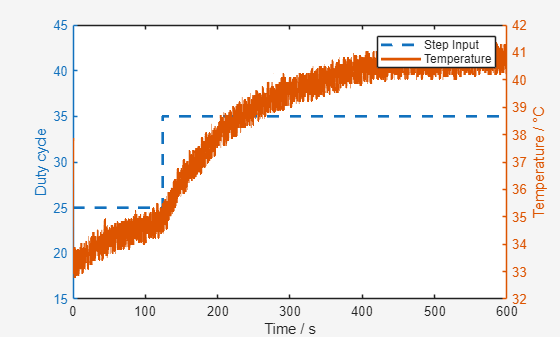

% load data
load("3_1_data.mat");
%data.plot

% extract data
data= data.getElement(3);
raw_step_y=data.getElement('Step Input');
raw_step_y=raw_step_y.Values.Data;
raw_temp_y=data.getElement('Temperature');
raw_temp_x= raw_temp_y.Values.Time;
raw_temp_y = squeeze(raw_temp_y.Values.Data);

f3_1=figure;

yyaxis left
plot(raw_temp_x, raw_step_y, 'LineWidth', 2, LineStyle='--');
ylim([15 45]);
ylabel('Duty cycle');

yyaxis right
plot(raw_temp_x, raw_temp_y, 'LineWidth', 2);
ylabel('Temperature / °C');

xlabel('Time / s');
%title('Raw Step Response and Temperature Data');
legend('Step Input', 'Temperature');
theme("light")
saveas(f3_1,"graphs/3_1_measured_step_raw.png")

## 3.1 Tidy up data and convert Step to unit Step

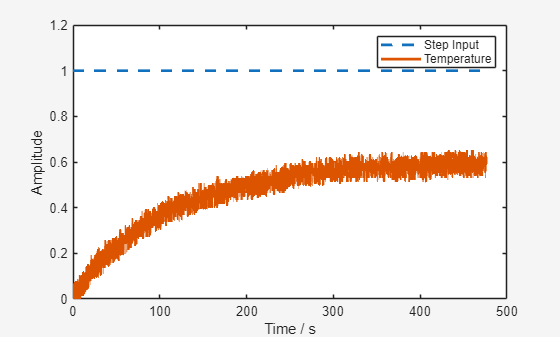

% measure temperature offset before the step 
% locate step
idx = find(raw_step_y > 25, 1, 'first');
temp_offset = mean(raw_temp_y(idx-100:idx));
step_offset = raw_step_y(1);
time_offset = (idx*1/100);
% create a unit step und exclude data before step

step_y = (raw_step_y(idx:end)-step_offset)/10;
temp_y = (raw_temp_y(idx:end)-temp_offset)/10;
temp_x = raw_temp_x(idx:end)-time_offset;


% plot
f3_1=figure;
plot(temp_x, step_y, 'LineWidth', 2, LineStyle='--');
ylim([0 1.2]);
xlim([0 500]);
ylabel('Step Input');
hold on;
plot(temp_x, temp_y, 'LineWidth', 2);
ylabel('Amplitude');
xlabel('Time / s');
%title('Unit-step response');
legend('Step Input', 'Temperature');
hold off;
theme("light")
saveas(f3_1,"graphs/3_1_measured_unit_step.png")

## 3.2 Fit PT1 + dead time model

% K=params(1);
% T=params(2);
% Tt=params(3);
pt1_tt_model = @(params, t) params(1) * (1 - exp(-(t - params(3))/params(2))).* (t >= params(3));


%% Initial guess for [K, T, Tt]
K0 = 50;
T0 = 300;
Tt0 = 0;
params0 = [K0, T0, Tt0];

%% Fit using lsqcurvefit
lb = [0, 0, 0];
ub = [];

opts = optimset('Display','iter');

params_fit = lsqcurvefit(pt1_tt_model, params0, temp_x, temp_y, lb,ub);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



%% Display results
K_fit = params_fit(1);
T_fit = params_fit(2);
Tt_fit = params_fit(3);
fprintf('Identified PT1+Tt system:\n');

Identified PT1+Tt system:


fprintf('Gain K = %.4f\n', K_fit);

Gain K = 0.5960


fprintf('Time constant T = %.4f s\n', T_fit); 

Time constant T = 107.2387 s


fprintf('Dead time Tt = %.4f s\n', Tt_fit);

Dead time Tt = 0.0000 s


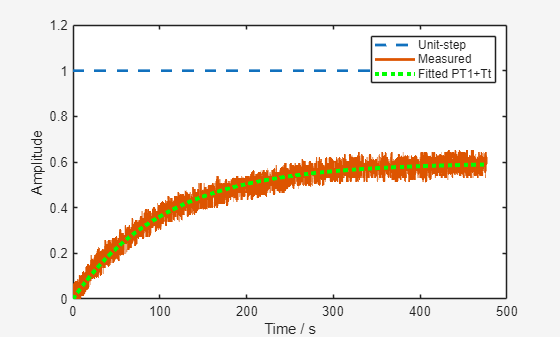


%% Plot fitted response
y_fit = pt1_tt_model(params_fit, temp_x);
f3_2=figure;
plot(temp_x, step_y, 'LineWidth', 2, LineStyle='--');
hold on;
plot(temp_x, temp_y, 'LineWidth', 2);
hold on;

plot(temp_x, y_fit, 'g:', 'LineWidth', 3);
ylim([0 1.2]);
xlim([0 500]);
xlabel('Time / s');
ylabel('Amplitude');
%title('Step Response: Original vs Fitted PT1+Tt Model');
legend('Unit-step','Measured', 'Fitted PT1+Tt');
hold off;
theme("light")
saveas(f3_2,"graphs/3_2_original_vs_fit.png")

## 3.2 Open loop simulation with fitted system -> both look similar (good)

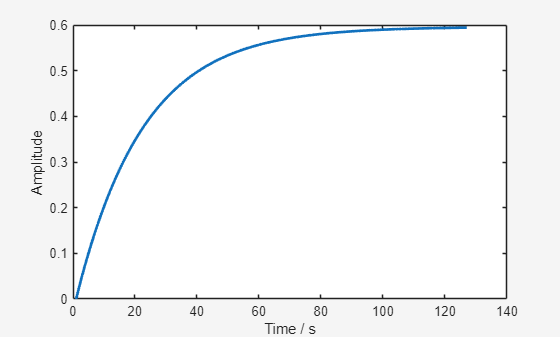

% calculation is simplified because fit and step response graph showed no
% signs of dead time 
s = tf('s');
G_s = K_fit / (T_fit*s + 1);
% G transfer function for a PT1 with deadtime
G_deadtime = K_fit * exp(-Tt_fit * s) / (T_fit * s + 1);
%G_s=G_deadtime
f3_2=figure;
h=step(G_s);
plot(h, LineWidth=2)
xlabel("Time / s")
ylabel("Amplitude")
theme("light")
%title('Step Response')
saveas(f3_2,"graphs/3_2_openloop_step.png")

# **Laboratory Session 2 : Temperature Control**

## 5.1 Ziegler Nichols Script

%parameters from measured step response
K_fit

K_fit = 0.5960

T_fit

T_fit = 107.2387

Tt_fit=0.2 %  use 0,2 here to avoid division /0

Tt_fit = 0.2000

Ts = temp_x(2)-temp_x(1) % sampling time in seconds

Ts = 0.0100

% parameters for Ziegler Nichols
Kp_ZN = (0.9 * T_fit) / (K_fit * Tt_fit)

Kp_ZN = 809.6334

Ti_ZN = 3.33 * Tt_fit

Ti_ZN = 0.6660

Ki_ZN = Kp_ZN * Ts % Ti passiert intern bei c2d

Ki_ZN = 8.0963

Kp_ZN = Kp_ZN/4

Kp_ZN = 202.4083


% Continuous and discrete controller %c stands for controller
%s = tf('s');
C_s_ZN = Kp_ZN * (1 + 1/(Ti_ZN*s))              % Continuous-time PI


C_s_ZN =
 
  134.8 s + 202.4
  ---------------
      0.666 s
 
Continuous-time transfer function.


C_z_ZN = c2d(C_s_ZN, Ts, 'tustin')        % Discretized PI


C_z_ZN =
 
  203.9 z - 200.9
  ---------------
       z - 1
 
Sample time: 0.01 seconds
Discrete-time transfer function.


## 5.2 Discrete pole placement


% --- Desired closed-loop settling time ---
t_settle = 20;                      % seconds
z_p = 1 - 4*Ts/t_settle;            % desired closed-loop pole location

% --- Continuous-time plant ---
G_s 


G_s =
 
     0.596
  -----------
  107.2 s + 1
 
Continuous-time transfer function.



% --- Discretize plant using backward Euler ---
G_z = c2d(G_s, Ts, 'tustin');       % this uses s = (z-1)/(z*Ts)

[numG, denG] = tfdata(G_z, 'v');
a = denG(2);
b = numG(2);

% --- Solve for PI parameters (pole placement) ---
% Closed-loop pole equation for discrete PI (using backward Euler form):
% z^2 + (b*Kp + a - 1)z + (b*Ki - a) = 0
Kp_PP = (z_p - a) / b

Kp_PP = 7.1895e+04

Ki_PP = (1 - z_p) / b

Ki_PP = 71.9708

Ti_PP = (Kp_PP * Ts) / Ki_PP

Ti_PP = 9.9895


fprintf("PI controller (backward Euler discretization):\n");

PI controller (backward Euler discretization):


fprintf("Kp = %.3f\nKi = %.3f\nDesired z_p = %.3f\n", Kp_PP, Ki_PP, z_p);

Kp = 71895.441
Ki = 71.971
Desired z_p = 0.998



% --- Discrete-time PI controller (backward Euler form) ---
z = tf('z', Ts);
C_z_PP = Kp_PP + Ki_PP * z / (z - 1)


C_z_PP =
 
  7.197e04 z - 7.19e04
  --------------------
         z - 1
 
Sample time: 0.01 seconds
Discrete-time transfer function.


## 5.3 see in simulink measurement

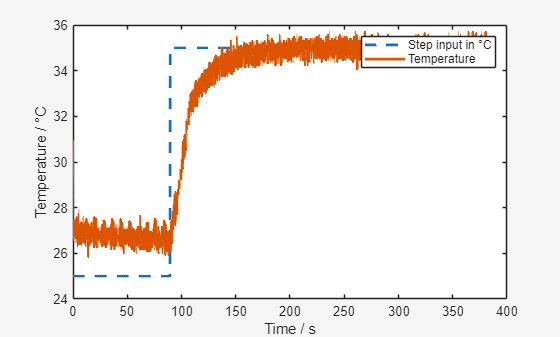

%file('TempControl_OpenLoop_5_3.slx')
data_5_3=load("5_3_data.mat");
% extract data
data_5_3 = data_5_3.data;
data_5_3 = data_5_3.getElement(13);
raw_step_y= data_5_3.getElement(4);
raw_step_y=raw_step_y.Values;
raw_step_y=raw_step_y.Data;
raw_temp_y=data_5_3.getElement('Temperature');
raw_temp_x= raw_temp_y.Values.Time;
raw_temp_y = squeeze(raw_temp_y.Values.Data);

f5_3=figure;
plot(raw_temp_x, raw_step_y, 'LineWidth', 2, DisplayName='Step input in °C', LineStyle='--');
hold on;
plot(raw_temp_x, raw_temp_y, 'LineWidth', 2, DisplayName='Temperature');
xlabel('Time / s')
ylabel('Temperature / °C')
legend()
theme("light")
saveas(f5_3,"graphs/5_3_ZN_step.png")

## We chose Ziegler Nichols because it`s controller values (with a simulated dead time of 0.2) were better, futhermore we divided the Kp facotr with 4 to make the control steadier.

## 5.4 Closed Loop Simulation in simulink

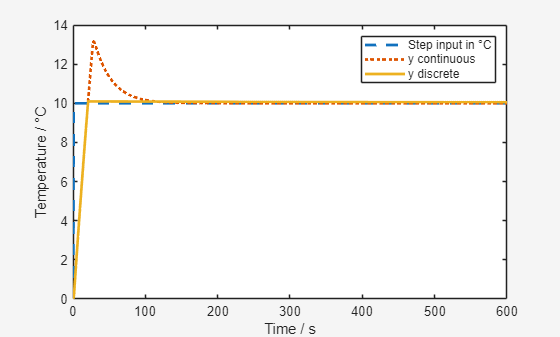

%file('TempControl_OpenLoop_5_4.slx')
% load data
data_5_4_sim=load("5_4_data_sim.mat");

% extract data
data_5_4 = data_5_4_sim.data;
data_5_4 = data_5_4.getElement(5);

raw_temp_y_cont= data_5_4.getElement('y_cont');
raw_temp_y_cont=raw_temp_y_cont.Values;
raw_temp_y_cont=raw_temp_y_cont.Data;
raw_temp_x_cont= data_5_4.getElement('y_cont');
raw_temp_x_cont=raw_temp_x_cont.Values;
raw_temp_x_cont=raw_temp_x_cont.Time;

raw_temp_y_dis= data_5_4.getElement('y_dis');
raw_temp_y_dis=raw_temp_y_dis.Values;
raw_temp_y_dis=raw_temp_y_dis.Data;
raw_temp_x_dis= data_5_4.getElement('y_dis');
raw_temp_x_dis=raw_temp_x_dis.Values;
raw_temp_x_dis=raw_temp_x_dis.Time;


raw_step_y=data_5_4.getElement('w_dis');
raw_step_y=raw_step_y.Values;
raw_step_y=raw_step_y.Data;
raw_step_x=data_5_4.getElement('w_dis');
raw_step_x=raw_step_x.Values;
raw_step_x=raw_step_x.Time;

f5_4=figure;
plot(raw_step_x, raw_step_y, 'LineWidth', 2, 'DisplayName','Step input in °C', LineStyle="--");
hold on;
plot(raw_temp_x_cont, raw_temp_y_cont, 'LineWidth', 2, 'DisplayName','y continuous', LineStyle=":");
hold on;
plot(raw_temp_x_dis, raw_temp_y_dis, 'LineWidth', 2, 'DisplayName','y discrete');
legend("show")
xlabel("Time / s")
ylabel("Temperature / °C")
theme("light")
saveas(f5_4,"graphs/5_4_closed_loop.png")

## 5.5 2DOF Control with trajectory

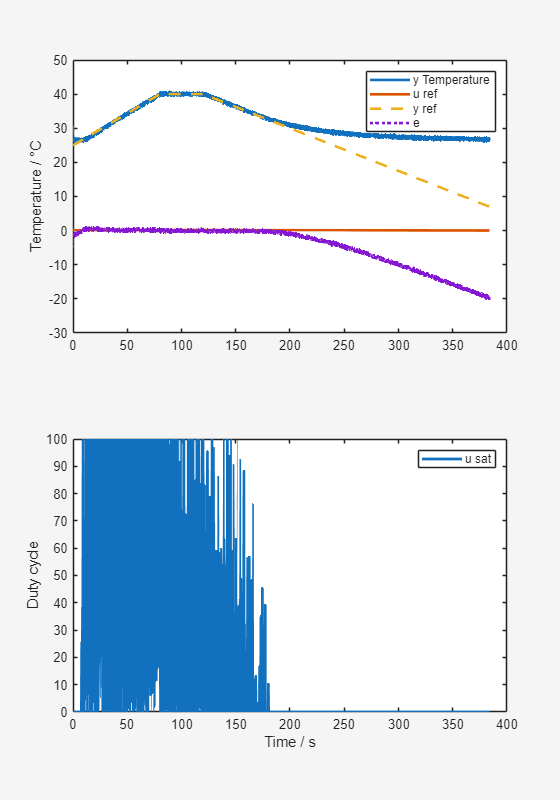

%file('TempControl_OpenLoop_5_5.slx')
data_5_5=load("5_5_data.mat");
% extract data
data_5_5 = data_5_5.data;
data_5_5 = data_5_5.getElement(16);

raw_temp_y= data_5_5.getElement('Temperature');
%raw_temp_y=raw_temp_y.Values;
%raw_temp_y=raw_temp_y.Data;
raw_temp_y = squeeze(raw_temp_y.Values.Data);
raw_temp_x= data_5_5.getElement('Temperature');
raw_temp_x=raw_temp_x.Values;
raw_temp_x=raw_temp_x.Time;

raw_uref_y= data_5_5.getElement('uref');
%raw_uref_y=raw_uref_y.Values;
%raw_uref_y=raw_uref_y.Data;
raw_uref_y = squeeze(raw_uref_y.Values.Data);
raw_uref_x= data_5_5.getElement('uref');
raw_uref_x=raw_uref_x.Values;
raw_uref_x=raw_uref_x.Time;

raw_yref_y= data_5_5.getElement('yref');
%raw_yref_y=raw_yref_y.Values;
%raw_yref_y=raw_yref_y.Data;
raw_yref_y = squeeze(raw_yref_y.Values.Data);
raw_yref_x= data_5_5.getElement('yref');
raw_yref_x=raw_yref_x.Values;
raw_yref_x=raw_yref_x.Time;

raw_usat_y= data_5_5.getElement('usat');
%raw_usat_y=raw_usat_y.Values;
%raw_usat_y=raw_usat_y.Data;
raw_usat_y = squeeze(raw_usat_y.Values.Data);
raw_usat_x= data_5_5.getElement('usat');
raw_usat_x=raw_usat_x.Values;
raw_usat_x=raw_usat_x.Time;

raw_e_y= data_5_5.getElement('e');
%raw_e_y=raw_e_y.Values;
%raw_e_y=raw_e_y.Data;
raw_e_y = squeeze(raw_e_y.Values.Data);
raw_e_x= data_5_5.getElement('e');
raw_e_x=raw_e_x.Values;
raw_e_x=raw_e_x.Time;


f5_5 = figure;
f5_5.Position = [100, 100, 560, 800];
ax1 = subplot(2, 1, 1); 

plot(raw_temp_x, raw_temp_y, 'LineWidth', 2, 'DisplayName','y Temperature');
hold on; 
plot(raw_uref_x, raw_uref_y, 'LineWidth', 2, 'DisplayName','u ref', LineStyle='-');
plot(raw_yref_x, raw_yref_y, 'LineWidth', 2, 'DisplayName','y ref', 'LineStyle','--');
plot(raw_e_x, raw_e_y, 'LineWidth', 2, 'DisplayName','e', LineStyle=':');
hold off;

legend("show");
ylabel("Temperature / °C"); 

ax2 = subplot(2, 1, 2); 


plot(raw_usat_x, raw_usat_y, 'LineWidth', 2, 'DisplayName','u sat', LineStyle='-');

legend("show");
ylabel("Duty cycle"); 
xlabel("Time / s"); 

linkaxes([ax1, ax2], 'x'); 

theme("light"); 
saveas(f5_5, "graphs/5_5_2dof_real.png");

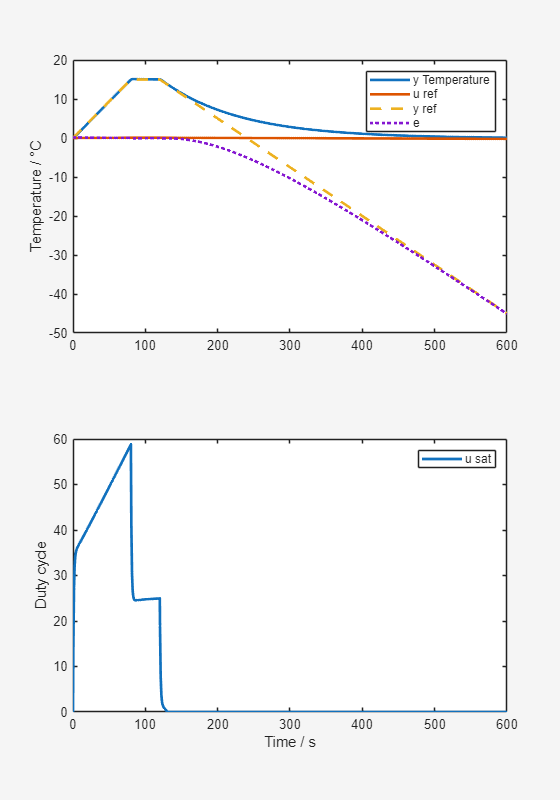


% 5_5 Simulation ohne Umgebungstemperatur
%file('TempControl_OpenLoop_5_5_sim.slx')
data_5_5_sim=load("5_5_data_sim.mat");

data_5_5_sim = data_5_5_sim.data;
data_5_5_sim = data_5_5_sim.getElement(4);

raw_temp_y= data_5_5_sim.getElement('y');
%raw_temp_y=raw_temp_y.Values;
%raw_temp_y=raw_temp_y.Data;
raw_temp_y = squeeze(raw_temp_y.Values.Data);
raw_temp_x= data_5_5_sim.getElement('y');
raw_temp_x=raw_temp_x.Values;
raw_temp_x=raw_temp_x.Time;

raw_uref_y= data_5_5_sim.getElement('uref');
%raw_uref_y=raw_uref_y.Values;
%raw_uref_y=raw_uref_y.Data;
raw_uref_y = squeeze(raw_uref_y.Values.Data);
raw_uref_x= data_5_5_sim.getElement('uref');
raw_uref_x=raw_uref_x.Values;
raw_uref_x=raw_uref_x.Time;

raw_yref_y= data_5_5_sim.getElement('yref');
%raw_yref_y=raw_yref_y.Values;
%raw_yref_y=raw_yref_y.Data;
raw_yref_y = squeeze(raw_yref_y.Values.Data);
raw_yref_x= data_5_5_sim.getElement('yref');
raw_yref_x=raw_yref_x.Values;
raw_yref_x=raw_yref_x.Time;

raw_usat_y= data_5_5_sim.getElement('usat');
%raw_usat_y=raw_usat_y.Values;
%raw_usat_y=raw_usat_y.Data;
raw_usat_y = squeeze(raw_usat_y.Values.Data);
raw_usat_x= data_5_5_sim.getElement('usat');
raw_usat_x=raw_usat_x.Values;
raw_usat_x=raw_usat_x.Time;

raw_e_y= data_5_5_sim.getElement('e');
%raw_e_y=raw_e_y.Values;
%raw_e_y=raw_e_y.Data;
raw_e_y = squeeze(raw_e_y.Values.Data);
raw_e_x= data_5_5_sim.getElement('e');
raw_e_x=raw_e_x.Values;
raw_e_x=raw_e_x.Time;

f5_5 = figure;
f5_5.Position = [100, 100, 560, 800]; 

ax1 = subplot(2, 1, 1); 

plot(raw_temp_x, raw_temp_y, 'LineWidth', 2, 'DisplayName','y Temperature');
hold on;
plot(raw_uref_x, raw_uref_y, 'LineWidth', 2, 'DisplayName','u ref', LineStyle='-');
plot(raw_yref_x, raw_yref_y, 'LineWidth', 2, 'DisplayName','y ref', 'LineStyle','--');
plot(raw_e_x, raw_e_y, 'LineWidth', 2, 'DisplayName','e', LineStyle=':');
hold off;

legend("show");
ylabel("Temperature / °C"); 


ax2 = subplot(2, 1, 2); 


plot(raw_usat_x, raw_usat_y, 'LineWidth', 2, 'DisplayName','u sat');

legend("show");
ylabel("Duty cycle"); 
xlabel("Time / s");

linkaxes([ax1, ax2], 'x'); 

theme("light"); 
saveas(f5_5, "graphs/5_5_2dof_sim.png");

## 5.6 Trajectory for a sintering Stove

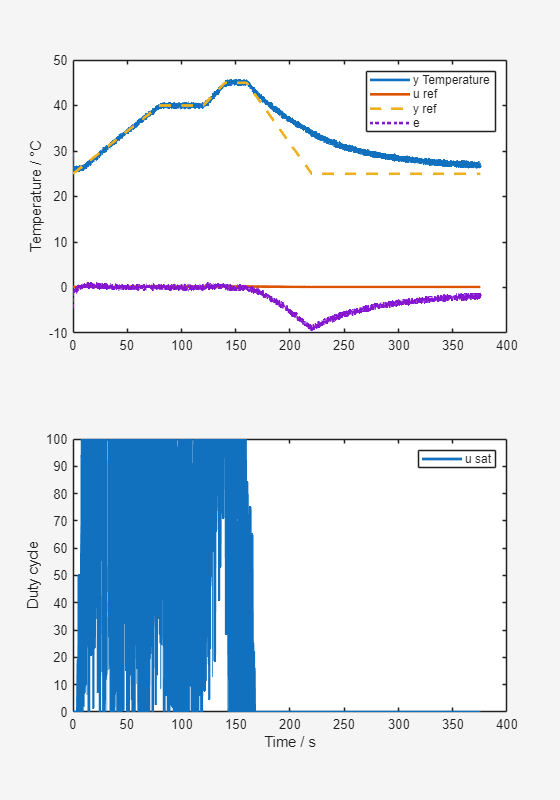

%file('TempControl_OpenLoop_5_6_sim.slx')
data_5_6=load("5_6_data.mat");

data_5_6 = data_5_6.data;
data_5_6 = data_5_6.getElement(21);

raw_temp_y= data_5_6.getElement('Temperature');
%raw_temp_y=raw_temp_y.Values;
%raw_temp_y=raw_temp_y.Data;
raw_temp_y = squeeze(raw_temp_y.Values.Data);
raw_temp_x= data_5_6.getElement('Temperature');
raw_temp_x=raw_temp_x.Values;
raw_temp_x=raw_temp_x.Time;

raw_uref_y= data_5_6.getElement('uref');
%raw_uref_y=raw_uref_y.Values;
%raw_uref_y=raw_uref_y.Data;
raw_uref_y = squeeze(raw_uref_y.Values.Data);
raw_uref_x= data_5_6.getElement('uref');
raw_uref_x=raw_uref_x.Values;
raw_uref_x=raw_uref_x.Time;

raw_yref_y= data_5_6.getElement('yref');
%raw_yref_y=raw_yref_y.Values;
%raw_yref_y=raw_yref_y.Data;
raw_yref_y = squeeze(raw_yref_y.Values.Data);
raw_yref_x= data_5_6.getElement('yref');
raw_yref_x=raw_yref_x.Values;
raw_yref_x=raw_yref_x.Time;

raw_usat_y= data_5_6.getElement('usat');
%raw_usat_y=raw_usat_y.Values;
%raw_usat_y=raw_usat_y.Data;
raw_usat_y = squeeze(raw_usat_y.Values.Data);
raw_usat_x= data_5_6.getElement('usat');
raw_usat_x=raw_usat_x.Values;
raw_usat_x=raw_usat_x.Time;

raw_e_y= data_5_6.getElement('e');
%raw_e_y=raw_e_y.Values;
%raw_e_y=raw_e_y.Data;
raw_e_y = squeeze(raw_e_y.Values.Data);
raw_e_x= data_5_6.getElement('e');
raw_e_x=raw_e_x.Values;
raw_e_x=raw_e_x.Time;

f5_6 = figure;
f5_6.Position = [100, 100, 560, 800];

ax1 = subplot(2, 1, 1); 

plot(raw_temp_x, raw_temp_y, 'LineWidth', 2, 'DisplayName','y Temperature');
hold on;
plot(raw_uref_x, raw_uref_y, 'LineWidth', 2, 'DisplayName','u ref', LineStyle='-');
plot(raw_yref_x, raw_yref_y, 'LineWidth', 2, 'DisplayName','y ref', 'LineStyle','--');
plot(raw_e_x, raw_e_y, 'LineWidth', 2, 'DisplayName','e', LineStyle=':');
hold off;

legend("show");
ylabel("Temperature / °C"); 


ax2 = subplot(2, 1, 2); 

plot(raw_usat_x, raw_usat_y, 'LineWidth', 2, 'DisplayName','u sat');

legend("show");
ylabel("Duty cycle"); 
xlabel("Time / s"); 


linkaxes([ax1, ax2], 'x'); 

theme("light"); 
saveas(f5_6, "graphs/5_6_2dof_stove_real.png"); 

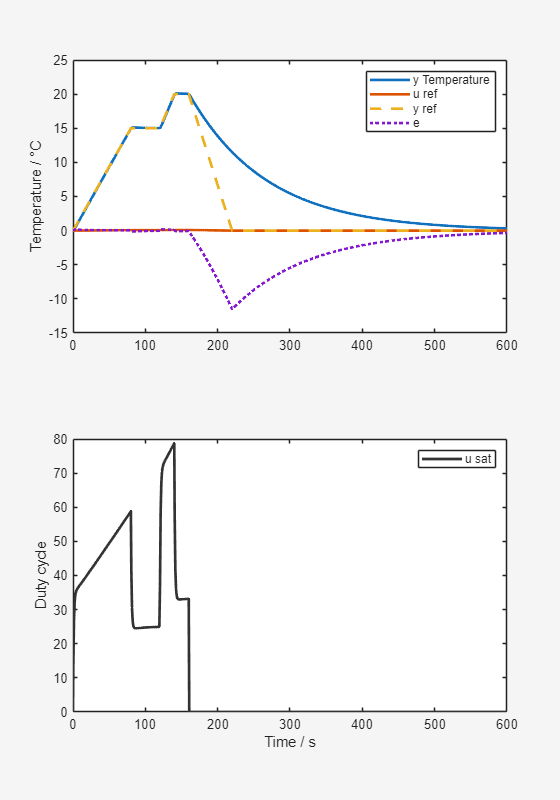



% 5_6 Simulation
%file('TempControl_OpenLoop_5_6_sim.slx')
data_5_6_sim=load("5_6_data_sim.mat");

data_5_6_sim = data_5_6_sim.data;
data_5_6_sim = data_5_6_sim.getElement(3);

raw_temp_y= data_5_6_sim.getElement('y');
%raw_temp_y=raw_temp_y.Values;
%raw_temp_y=raw_temp_y.Data;
raw_temp_y = squeeze(raw_temp_y.Values.Data);
raw_temp_x= data_5_6_sim.getElement('y');
raw_temp_x=raw_temp_x.Values;
raw_temp_x=raw_temp_x.Time;

raw_uref_y= data_5_6_sim.getElement('uref');
%raw_uref_y=raw_uref_y.Values;
%raw_uref_y=raw_uref_y.Data;
raw_uref_y = squeeze(raw_uref_y.Values.Data);
raw_uref_x= data_5_6_sim.getElement('uref');
raw_uref_x=raw_uref_x.Values;
raw_uref_x=raw_uref_x.Time;

raw_yref_y= data_5_6_sim.getElement('yref');
%raw_yref_y=raw_yref_y.Values;
%raw_yref_y=raw_yref_y.Data;
raw_yref_y = squeeze(raw_yref_y.Values.Data);
raw_yref_x= data_5_6_sim.getElement('yref');
raw_yref_x=raw_yref_x.Values;
raw_yref_x=raw_yref_x.Time;

raw_usat_y= data_5_6_sim.getElement('usat');
%raw_usat_y=raw_usat_y.Values;
%raw_usat_y=raw_usat_y.Data;
raw_usat_y = squeeze(raw_usat_y.Values.Data);
raw_usat_x= data_5_6_sim.getElement('usat');
raw_usat_x=raw_usat_x.Values;
raw_usat_x=raw_usat_x.Time;

raw_e_y= data_5_6_sim.getElement('e');
%raw_e_y=raw_e_y.Values;
%raw_e_y=raw_e_y.Data;
raw_e_y = squeeze(raw_e_y.Values.Data);
raw_e_x= data_5_6_sim.getElement('e');
raw_e_x=raw_e_x.Values;
raw_e_x=raw_e_x.Time;

f5_6 = figure;
f5_6.Position = [100, 100, 560, 800];

ax1 = subplot(2, 1, 1); 
plot(raw_temp_x, raw_temp_y, 'LineWidth', 2, 'DisplayName','y Temperature');
hold on;
plot(raw_uref_x, raw_uref_y, 'LineWidth', 2, 'DisplayName','u ref', LineStyle='-');
plot(raw_yref_x, raw_yref_y, 'LineWidth', 2, 'DisplayName','y ref', 'LineStyle','--');
plot(raw_e_x, raw_e_y, 'LineWidth', 2, 'DisplayName','e', LineStyle=':');
hold off;
legend("show");
ylabel("Temperature / °C"); 

ax2 = subplot(2, 1, 2); 
plot(raw_usat_x, raw_usat_y, 'LineWidth', 2, 'DisplayName','u sat','Color', [0.2 0.2 0.2 0.01]);
legend("show");
ylabel("Duty cycle"); 
xlabel("Time / s"); 

linkaxes([ax1, ax2], 'x'); 
theme("light"); 
saveas(f5_6, "graphs/5_6_2dof_stove_sim.png");

## Zusatz: Ideal Closed Loop Simulation continuous Ziegler Nichols `sättigung fehlt`


% PI-Regler in s-Domäne
C_s_ZN


C_s_ZN =
 
  134.8 s + 202.4
  ---------------
      0.666 s
 
Continuous-time transfer function.


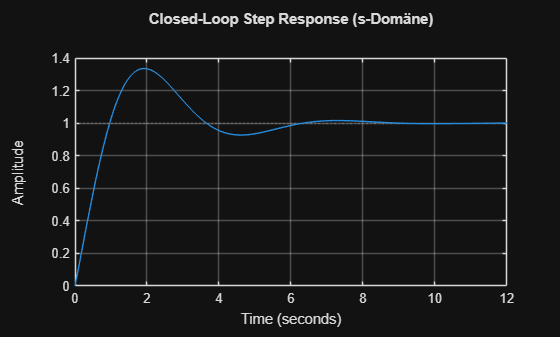

% Offene Strecke
G_open = series(C_s_ZN, G_s);

% Geschlossener Regelkreis
T_s = feedback(G_open, 1);

% Step Response
figure;
step(T_s);
title('Closed-Loop Step Response (s-Domäne)');
grid on;

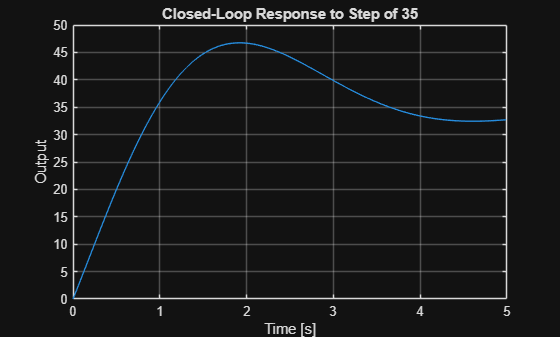

% Beispiel: Step von 0 auf 35
t = 0:Ts:5;              % Zeitvektor
u = 35 * ones(size(t));   % Eingabe: konstante 35

% Alternative: mit lsim für benutzerdefinierte Eingabe
y = lsim(T_s, u, t);

% Plot
figure;
plot(t, y);
title('Closed-Loop Response to Step of 35');
xlabel('Time [s]');
ylabel('Output');
grid on;

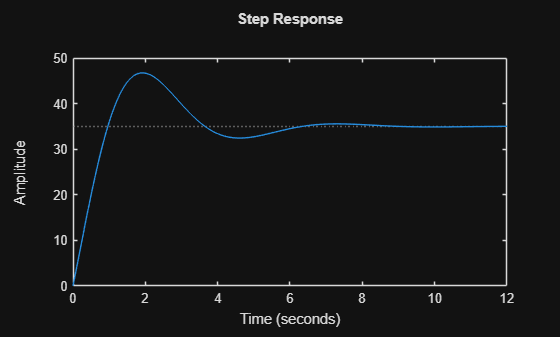

step(35*T_s)

## Zusatz: Ideal Closed Loop Simulation discrete, Poleplacement `sättigung fehlt`

G_s_z = c2d(G_s, Ts, 'tustin')


G_s_z =
 
  2.779e-05 z + 2.779e-05
  -----------------------
        z - 0.9999
 
Sample time: 0.01 seconds
Discrete-time transfer function.


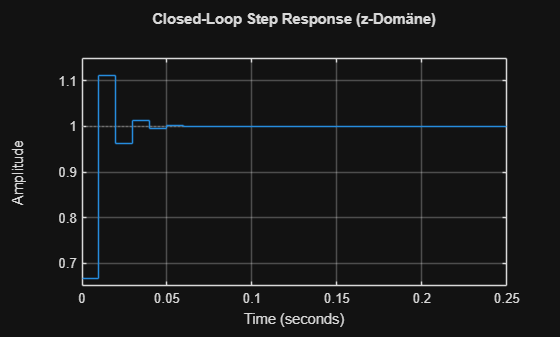


% Offene Strecke
G_open_z = series(C_z_PP, G_s_z);
% Geschlossener Regelkreis
T_z = feedback(G_open_z, 1);

% Step Response
figure;
step(T_z);
title('Closed-Loop Step Response (z-Domäne)');
grid on;

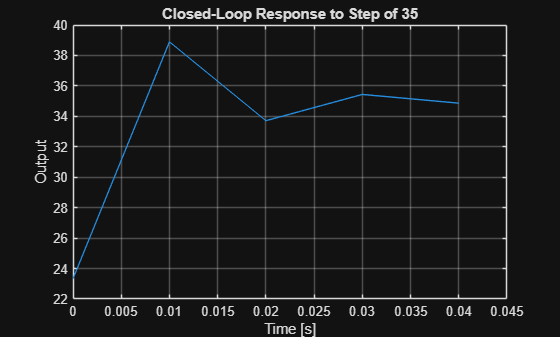

% Beispiel: Step von 0 auf 35
t = 0:Ts:0.05;              % Zeitvektor 
u = 35 * ones(size(t));   % Eingabe: konstante 35


% Alternative: mit lsim für benutzerdefinierte Eingabe
y = lsim(T_z, u, t);

% Plot
figure;
plot(t, y);
title('Closed-Loop Response to Step of 35');
xlabel('Time [s]');
ylabel('Output');
grid on;